clear all
clc

% Parameters 
r1 = 1.5; r2 = 1.0;     % grow rate
b1 = 1.0; b2 = 1.0;     % saturation rate
c1 = 1; c2 = 0.5; c3 = 1.0; c4 = 1.0;     % competivity rate
rho = 0.01; alpha = 0.3;
s = 0.33;    % immune constant supply
d1 = 0.2;  % mortality rate for immune cells

tspan = [0, 100];  


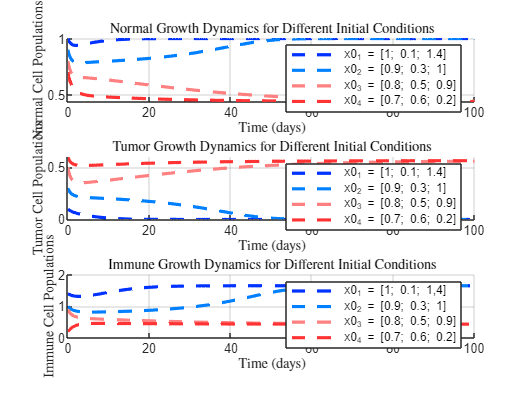

%% Autonomous System
x0_1 = [1; 0.1; 1.4]; 
x0_2 = [0.9; 0.3; 1]; 
x0_3 = [0.8; 0.5; 0.9]; 
x0_4 = [0.7; 0.6; 0.2]; 

[t, x1] = ode45(@(t, x) tumor_growth(t, x, r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1), tspan, x0_1);
[t2, x2] = ode45(@(t, x) tumor_growth(t, x, r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1), tspan, x0_2);
[t3, x3] = ode45(@(t, x) tumor_growth(t, x, r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1), tspan, x0_3);
[t4, x4] = ode45(@(t, x) tumor_growth(t, x, r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1), tspan, x0_4);

% Normal Cell Populations
figure;
subplot(3,1,1);
hold on;
plot(t, x1(:,1), 'LineWidth', 2, 'Color', [0 0.2 1], 'LineStyle', '--', 'DisplayName', 'x0_1 = [1; 0.1; 1.4]');
plot(t2, x2(:,1), 'LineWidth', 2, 'Color', [0 0.5 1], 'LineStyle', '--','DisplayName', 'x0_2 = [0.9; 0.3; 1]'); 
plot(t3, x3(:,1), 'LineWidth', 2, 'Color', [1 0.5 0.5], 'LineStyle', '--', 'DisplayName', 'x0_3 = [0.8; 0.5; 0.9]'); 
plot(t4, x4(:,1), 'LineWidth', 2, 'Color', [1 0.2 0.2], 'LineStyle', '--', 'DisplayName', 'x0_4 = [0.7; 0.6; 0.2]'); 
xlabel('Time (days)', 'Interpreter', 'latex');
ylabel('Normal Cell Populations', 'Interpreter', 'latex');
title('Normal Growth Dynamics for Different Initial Conditions', 'Interpreter', 'latex');
legend('show');
grid on;

% Tumor Cell Populations
subplot(3,1,2);
hold on;
plot(t, x1(:,2), 'LineWidth', 2, 'Color', [0 0.2 1], 'LineStyle', '--', 'DisplayName', 'x0_1 = [1; 0.1; 1.4]'); 
plot(t2, x2(:,2), 'LineWidth', 2, 'Color', [0 0.5 1],'LineStyle', '--', 'DisplayName', 'x0_2 = [0.9; 0.3; 1]'); 
plot(t3, x3(:,2), 'LineWidth', 2, 'Color', [1 0.5 0.5], 'LineStyle', '--', 'DisplayName', 'x0_3 = [0.8; 0.5; 0.9]'); 
plot(t4, x4(:,2), 'LineWidth', 2, 'Color', [1 0.2 0.2], 'LineStyle', '--', 'DisplayName', 'x0_4 = [0.7; 0.6; 0.2]'); 
xlabel('Time (days)', 'Interpreter', 'latex');
xlabel('Time (days)', 'Interpreter', 'latex');
ylabel('Tumor Cell Populations', 'Interpreter', 'latex');
title('Tumor Growth Dynamics for Different Initial Conditions', 'Interpreter', 'latex');
legend('show');
grid on;

% Immune Cell Populations
subplot(3,1,3);
hold on;
plot(t, x1(:,3), 'LineWidth', 2, 'Color', [0 0.2 1], 'LineStyle', '--', 'DisplayName', 'x0_1 = [1; 0.1; 1,4]'); 
plot(t2, x2(:,3), 'LineWidth', 2, 'Color', [0 0.5 1],'LineStyle', '--', 'DisplayName', 'x0_2 = [0.9; 0.3; 1]'); 
plot(t3, x3(:,3), 'LineWidth', 2, 'Color', [1 0.5 0.5],'LineStyle', '--', 'DisplayName', 'x0_3 = [0.8; 0.5; 0.9]'); 
plot(t4, x4(:,3), 'LineWidth', 2, 'Color', [1 0.2 0.2], 'LineStyle', '--', 'DisplayName', 'x0_4 = [0.7; 0.6; 0.2]'); 
xlabel('Time (days)', 'Interpreter', 'latex');
xlabel('Time (days)', 'Interpreter', 'latex');
ylabel('Immune Cell Populations', 'Interpreter', 'latex');
title('Immune Growth Dynamics for Different Initial Conditions', 'Interpreter', 'latex');
legend('show');
grid on;

hold off;

## EQUILIBRIUM POINT

syms x1 x2 x3

eq1 = r2 * x1 * (1 - b2 * x1) - c4 * x2 * x1 == 0;
eq2 = r1 * x2 * (1 - b1 * x2) - c2 * x3 * x2 - c3 * x2 * x1 == 0;
eq3 = s + (rho * x3 * x2) / (alpha + x2) - c1 * x3 * x2 - d1 * x3 == 0;

sol = vpasolve([eq1, eq2, eq3], [x1, x2, x3]);

disp('Intersection points (x1, x2, x3):');

Intersection points (x1, x2, x3):


disp([double(sol.x1), double(sol.x2), double(sol.x3)]);

    1.2916   -0.2916    1.2916
    0.4352    0.5648    0.4352
    0.7632    0.2368    0.7632
         0         0    1.6500
    1.0000         0    1.6500
         0    0.8992    0.3023
         0   -0.2832    3.8497
         0   -0.1060    3.3180



## PHASE PORTRAIT

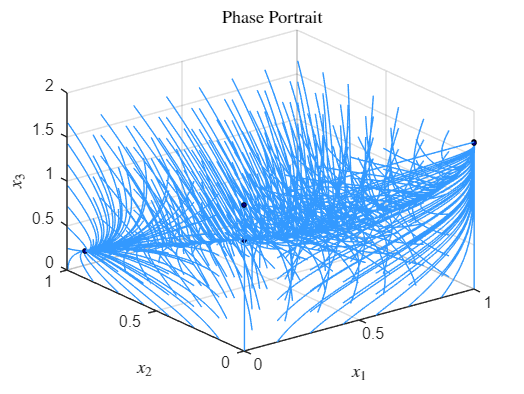

x_min = [0; 0; 0]; 
x_max = [1; 1; 1.65];  
npoints = 8;  

[x1_grid, x2_grid, x3_grid] = ndgrid(...
    linspace(x_min(1), x_max(1), npoints), ...
    linspace(x_min(2), x_max(2), npoints), ...
    linspace(x_min(3), x_max(3), npoints));
figure
hold on
grid on
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')
zlabel('$x_3$', 'Interpreter', 'latex')
title('Phase Portrait', 'Interpreter', 'latex')
view(3)

for i = 1:numel(x1_grid)
    initial_point = [x1_grid(i); x2_grid(i); x3_grid(i)];
    [t, x] = ode45(@(t, x) tumor_growth(t, x, r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1), [0, 250], initial_point);
    plot3(x(:, 1), x(:, 2), x(:, 3), 'Color', [0.2, 0.6, 1]); 
    plot3(x(end, 1), x(end, 2), x(end, 3), 'ko', 'MarkerFaceColor', [0, 0, 0.5], 'MarkerSize', 3); 
    drawnow;
end

## Lyapunov stability

syms x1 x2 x3

eq1 = r2 * x1 * (1 - b2 * x1) - c4 * x2 * x1 == 0;
eq2 = r1 * x2 * (1 - b1 * x2) - c2 * x3 * x2 - c3 * x2 * x1 == 0;
eq3 = s + (rho * x3 * x2) / (alpha + x2) - c1 * x3 * x2 - d1 * x3 == 0;

sol = vpasolve([eq1, eq2, eq3], [x1, x2, x3]);

disp('Intersection points (x1, x2, x3):');

Intersection points (x1, x2, x3):


disp([double(sol.x1), double(sol.x2), double(sol.x3)]);

    1.2916   -0.2916    1.2916
    0.4352    0.5648    0.4352
    0.7632    0.2368    0.7632
         0         0    1.6500
    1.0000         0    1.6500
         0    0.8992    0.3023
         0   -0.2832    3.8497
         0   -0.1060    3.3180



xi_eq = [double(sol.x1(5,:)), double(sol.x2(5,:)), double(sol.x3(5,:))]'

xi_eq =     1.0000
         0
    1.6500



% grid details
side = 0.1;
step = 0.01;

%grid points coordinates
xi_1_vec = xi_eq(1) - side : step : xi_eq(1) + side;
xi_2_vec = xi_eq(2) - side : step : xi_eq(2) + side;
xi_3_vec = xi_eq(3) - side : step : xi_eq(3) + side;
%Vdot initialization
Vdot = zeros(length(xi_1_vec), length(xi_2_vec), length(xi_3_vec));

%Vdot copmutation
for i = 1 : length(xi_1_vec)
    for j = 1 : length(xi_2_vec)
        for h = 1 : length(xi_3_vec)
            Vdot(i, j, h) = V_dot_fun([xi_1_vec(i); xi_2_vec(j); xi_3_vec(h)], t, xi_eq, r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1);
        end
    end
end

find(Vdot > 0)


ans =

  0×1 empty double column vector



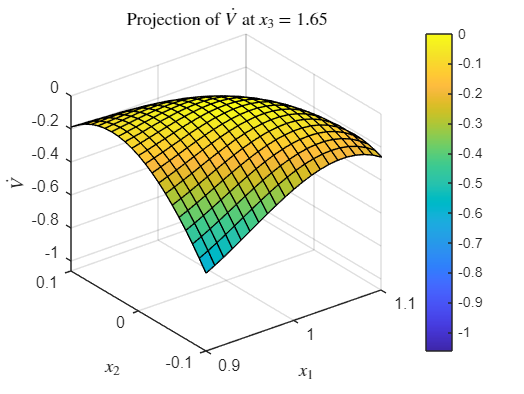

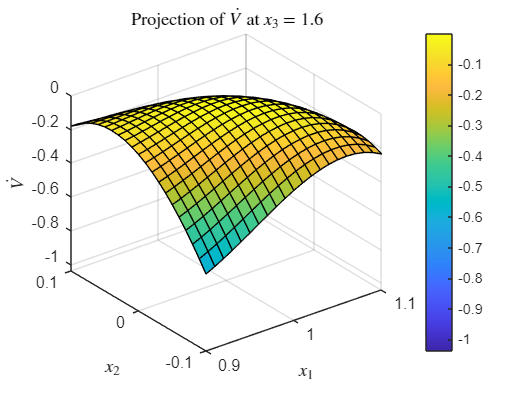

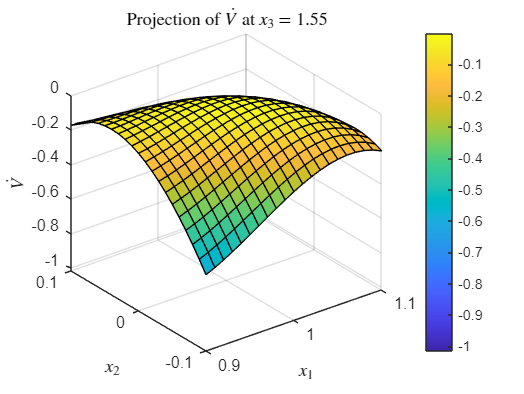

%% 1. Proiezioni per diversi valori di x3
x3_values = [1.65, 1.60, 1.55];  

for k = 1:length(x3_values)
    figure
    [~, idx] = min(abs(xi_3_vec - x3_values(k))); 
    
    if ~isempty(idx)
        
        Vdot_projection = Vdot(:,:,idx); 
        [xi_1_mesh, xi_2_mesh] = meshgrid(xi_1_vec, xi_2_vec);

        surf(xi_1_mesh, xi_2_mesh, Vdot_projection);
        xlabel('$x_1$', 'Interpreter', 'latex')
        ylabel('$x_2$', 'Interpreter', 'latex')
        zlabel('$\dot{V}$', 'Interpreter', 'latex')
        title(['Projection of $\dot{V}$ at $x_3 = ' num2str(x3_values(k)) '$'], 'Interpreter', 'latex')
        colorbar
    else
        disp(['No projection found for x3 = ' num2str(x3_values(k))])
    end
end

%% JACOBIAN
normal_cells =   0 ;  
tumor_cells =  -0.1060;    
immune_cells =  3.3180 ;   

J = [
    r2 * (1 - 2 * b2 * normal_cells) - c4 * tumor_cells,  -c4 * normal_cells,   0;
    -c3 * tumor_cells,   r1 * (1 - 2 * b1 * tumor_cells) - c2 * immune_cells - c3 * normal_cells,  -c2 * tumor_cells;
    0,   (rho * alpha * immune_cells) / ( (alpha + tumor_cells)^2 ) - c1 * immune_cells,   (rho * tumor_cells) / (alpha + tumor_cells) - c1 * tumor_cells - d1
];


eigenvalues = eig(J);

disp('Jacobian Matrix J_f:');

Jacobian Matrix J_f:


disp(J);

    1.1060         0         0
    0.1060    0.1590    0.0530
         0   -3.0535   -0.0995



disp('Eigenvalues');

Eigenvalues


disp(eigenvalues);

   0.0298 + 0.3810i
   0.0298 - 0.3810i
   1.1060 + 0.0000i



## RAS ESTIMATION

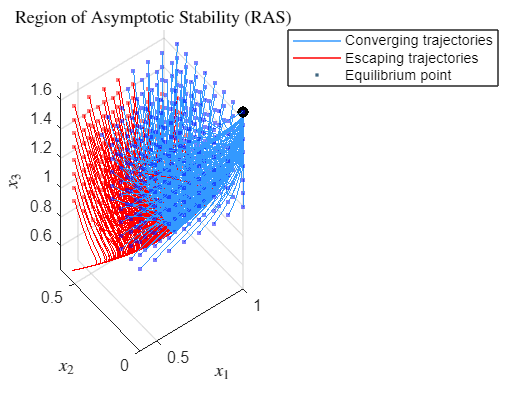

x_eq = [1; 0; 1.65];  
x0 = [0.8; 0.15; 1.5];
tspan = [0, 300];  

x_min = [0.4; 0; 1];  
x_max = [1.0; 0.5; 1.65];  
npoints = 8;  

epsilon = 1e-3;  

[x1_grid, x2_grid, x3_grid] = ndgrid(...
    linspace(x_min(1), x_max(1), npoints), ...
    linspace(x_min(2), x_max(2), npoints), ...
    linspace(x_min(3), x_max(3), npoints));

converging_points = [];
diverging_points = [];

figure
hold on
grid on
xlabel('$x_1$', 'Interpreter', 'latex')
ylabel('$x_2$', 'Interpreter', 'latex')
zlabel('$x_3$', 'Interpreter', 'latex')
title('Region of Asymptotic Stability (RAS)', 'Interpreter', 'latex')
view(3)

% Loop su tutti i punti iniziali
for i = 1:numel(x1_grid)
    initial_point = [x1_grid(i); x2_grid(i); x3_grid(i)];

    [t, x] = ode45(@(t, x) tumor_growth(t, x, r1, r2, b1, b2, c1, c2, c3, c4, rho, alpha, s, d1), tspan, initial_point);

    if norm(x(end, :)' - x_eq) < epsilon
        plot3(x(:, 1), x(:, 2), x(:, 3), 'Color', [0.2, 0.6, 1]); 
        converging_points = [converging_points, initial_point];
    else
        plot3(x(:, 1), x(:, 2), x(:, 3), 'Color', [1, 0, 0]);  
        diverging_points = [diverging_points, initial_point];
    end
    drawnow;
end

scatter3(converging_points(1, :), converging_points(2, :), converging_points(3, :), ...
    10, 'b', 'filled', 'MarkerFaceAlpha', 0.5);
scatter3(diverging_points(1, :), diverging_points(2, :), diverging_points(3, :), ...
    10, 'r', 'filled', 'MarkerFaceAlpha', 0.5);
scatter3(x_eq(1), x_eq(2), x_eq(3), 50, 'k', 'filled', 'Marker', 'o');

leg{1} = plot(NaN,'Color',[0.2, 0.6, 1]); 
leg{2} = plot(NaN,'Color',[1, 0, 0]);
leg{3} = plot(NaN,'.','Color','#406780'); 
legend([leg{:}], {'Converging trajectories','Escaping trajectories', 'Equilibrium point'})